# Set data

N = 257; % x,y sampling points
lambda = 633; % wavelength in nm
k = 2*pi/lambda;
Endpoint = 1.2E-3*lambda; % size/2
w = 0.7E-3*lambda; % rect width

## Create field at starting point (z=0)

z = 0

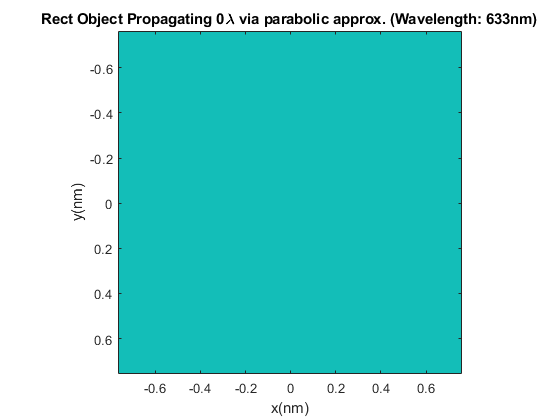

z = 63.3000

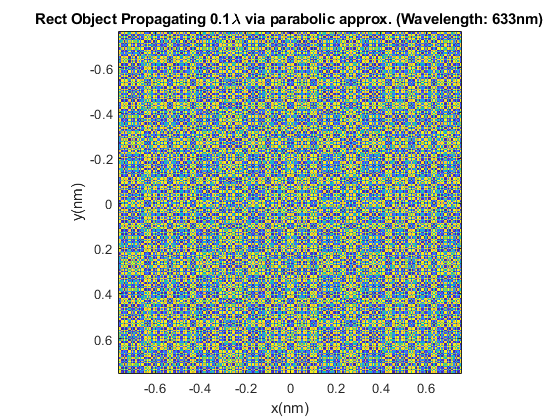

z = 126.6000

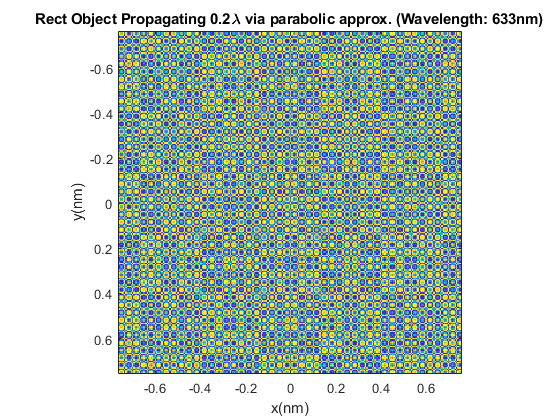

z = 189.9000

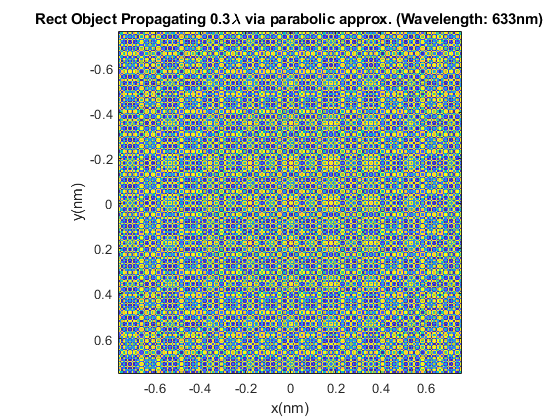

z = 253.2000

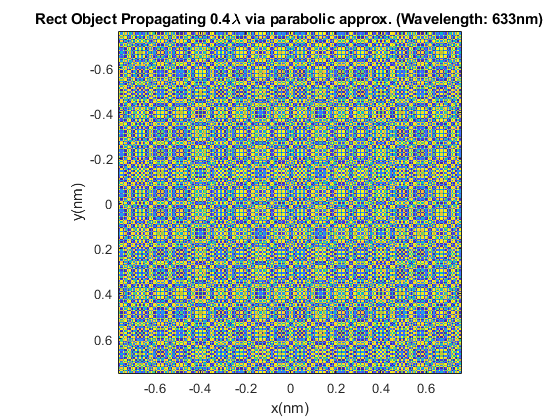

z = 316.5000

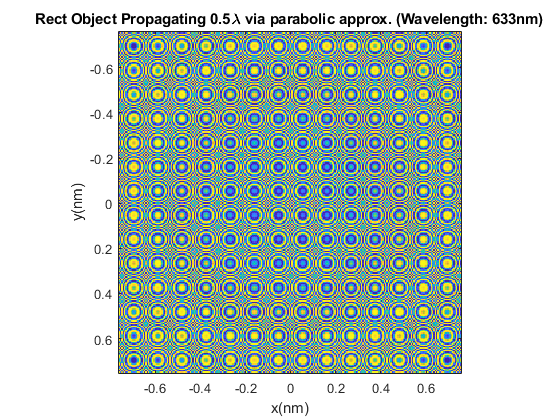

z = 379.8000

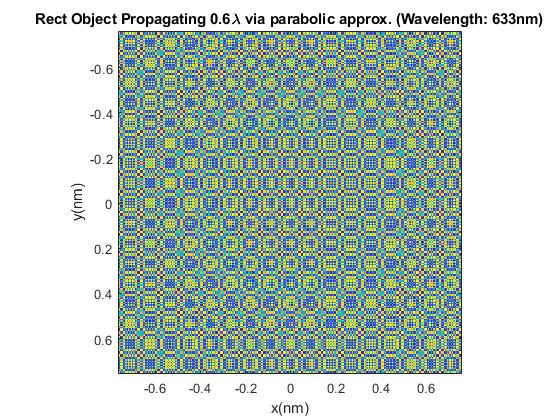

z = 443.1000

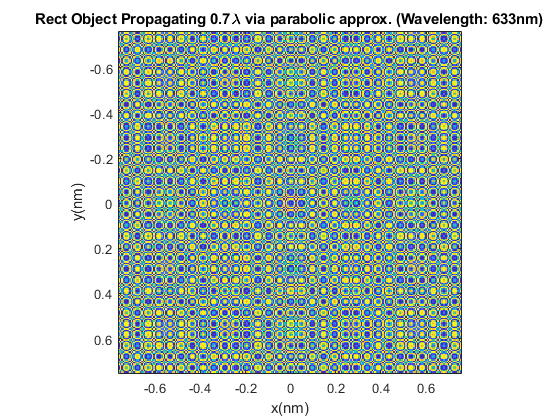

z = 506.4000

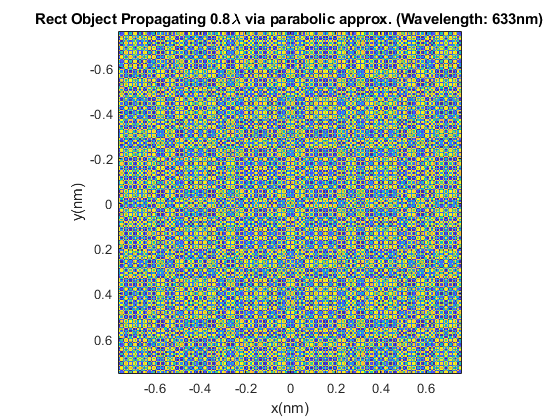

z = 569.7000

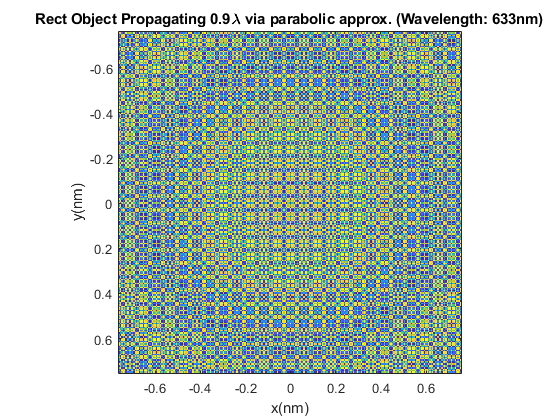

z = 633

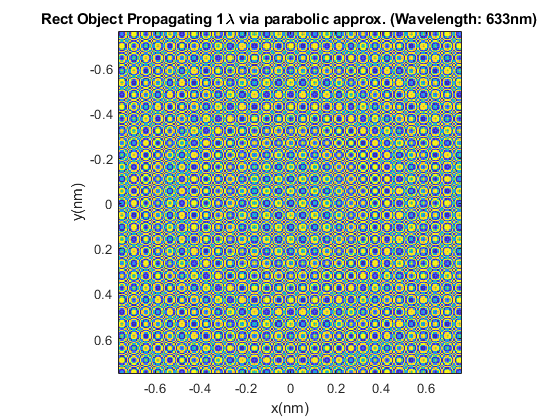

x = linspace(-Endpoint,Endpoint,N); 
x = x(1:end-1); 
dx = x(2)-x(1);
xi = linspace(-dx/2,dx/2,N); 
xi = xi(1:end-1); 
y = linspace(-Endpoint,Endpoint,N);
y = y(1:end-1);
dy = y(2)-y(1);
eta = linspace(-dy/2,dy/2,N);
eta = eta(1:end-1);
[X,Y] = meshgrid(x,y);


for k = 0:0.1:1
    z = k*lambda % propargate distance
    z = reshape(repmat(z,256*256,1),256,256,[]);
    Uph = exp(2*pi*1i*sqrt((lambda^-2)-(X.^2+Y.^2)).*z);
    U = Uph;
    H = exp(1i*k.*z).*exp(-1i*pi*lambda .*z.*(X.^2+ Y.^2));
    U_p = H;   
   
    figure()
    imagesc(x,y,real(U_p))
    axis square
    title(['Rect Object Propagating ' num2str(k) '\lambda via parabolic approx. (Wavelength: ' num2str(lambda) 'nm)'])
    xlabel('x(nm)')
    ylabel('y(nm)')
%     saveas(gcf,"Q4_figure/HW4_Q4_parabolic_approximation_"+num2str(10*k),'jpg')
end

## Plot Free-space transfer function exact for

z = 10*lambda

z = 6330

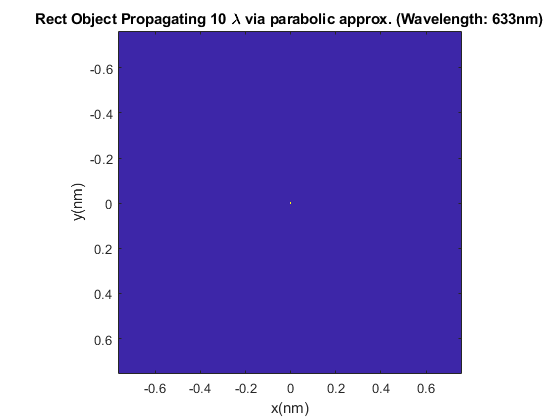

imagesc(x,y,real(U))
axis square
title(['Rect Object Propagating 10 \lambda via parabolic approx. (Wavelength: ' num2str(lambda) 'nm)'])
xlabel('x(nm)')
ylabel('y(nm)')

% saveas(gcf,"Q4_figure/HW4_Q4_parabolic_approximation_"+num2str(10*k),'jpg')